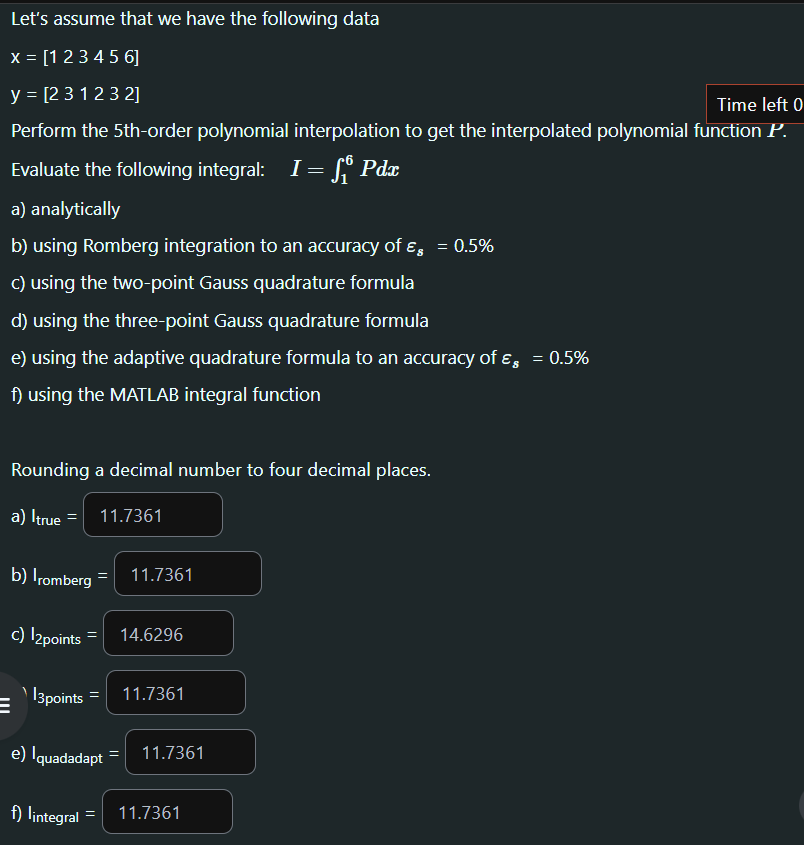

Function

x = [1 2 3 4 5 6];
y = [2 3 1 2 3 2];

coefficients = polyfit(x, y, 5);
% P = polyval(coefficients, x)

% f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;
f=@(x) polyval(coefficients, x)

f = function_handle with value:
    @(x)polyval(coefficients,x)


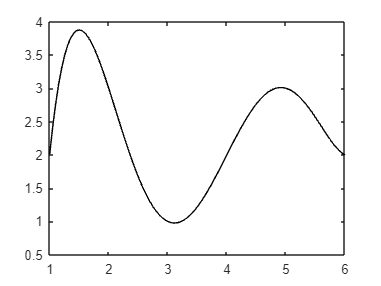


xx = linspace(1, 6);
yy = f(xx);
plot(xx,yy,'k-')

To integrate function from 0 to 0.8

a = 1;
b = 6;

p = coefficients;
q = polyint(p);

Itrue = diff(polyval(q, [a b]))

Itrue = 11.7361

Compute using composite trapezoidal rule

ns = 200;

for k = 1:ns
    I_trap(k) = trap(f,a,b,k);
    err(k) = ( (Itrue - I_trap(k) ) / Itrue) * 100;
end

[(1:ns)' I_trap' err']

ans =     1.0000   10.0000   14.7929
    2.0000    8.0469   31.4349
    3.0000    9.8285   16.2539
    4.0000   10.6104    9.5923
    5.0000   11.0000    6.2722
    6.0000   11.2190    4.4059
    7.0000   11.3536    3.2592
    8.0000   11.4420    2.5064
    9.0000   11.5030    1.9864
   10.0000   11.5469    1.6124


Compute using Romberg integration

[I_romberg, ea, iter] = romberg(f,a,b)

I_romberg = 11.7361

ea = 1.5136e-14

iter = 3

Compute using Gauss-Legendre Formulas

a1 = (b+a)/2;

a1 = 3.5000

a2 = (b-a)/2;

a2 = 2.5000


% x = a1 + a2 * xd
% dx = a2 + dxd

% f2=@(xd) (400.*(a1 + a2 * xd).^5 - 900.*(a1 + a2 * xd).^4 + 675.*(a1 + a2 * xd).^3 - 200.*(a1 + a2 * xd).^2 + 25.*(a1 + a2 * xd) + 0.2)*a2;
f2=@(xd) f(a1 + a2 * xd)*a2;
I_2_points = f2(-1/sqrt(3)) + f2(1/sqrt(3))

I_2_points = 14.6296

I_3_points = (5/9) * f2(-sqrt(3/5)) + ((8/9)*f2(0)) + (5/9)*f2(sqrt(3/5))

I_3_points = 11.7361

I_4_points = ((18 - sqrt(30))/36) * f2( (-sqrt( 525+70*sqrt(30) ))/35 ) + ((18 + sqrt(30))/36) * f2( (-sqrt( 525-70*sqrt(30) ))/35 ) + ((18 + sqrt(30))/36) * f2( (sqrt( 525-70*sqrt(30) ))/35 ) + ((18 - sqrt(30))/36) * f2( (sqrt( 525+70*sqrt(30) ))/35 )

I_4_points = 11.7361

Compute using adaptive quadrature

I_quadadapt = quadadapt(f,a,b)

I_quadadapt = 11.7361

Compute using Matlab's integral function

I_integral = integral(f,a,b)

I_integral = 11.7361